Part1

clear
load dtmri
whos

  Name        Size                 Bytes  Class      Attributes

  S         115x90x64            5299200  double               
  S0        115x90                 82800  double               
  b           1x1                      8  double               
  g          64x3                   1536  double               
  mask      115x90                 10350  logical              



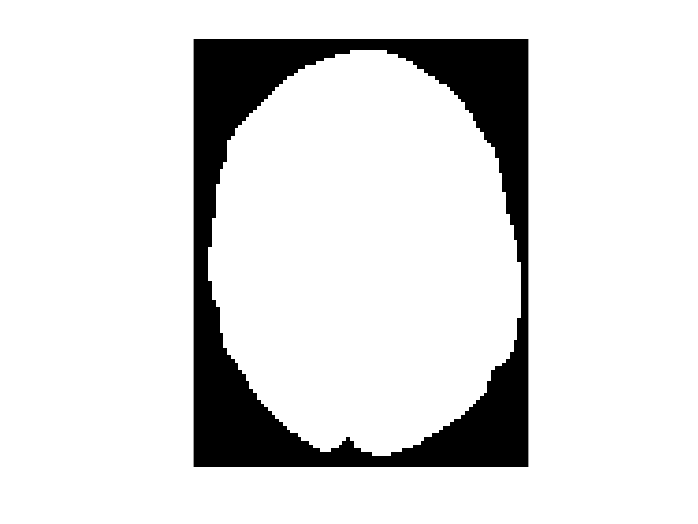

figure, imshow(mask, 'initialmagnification', 'fit')

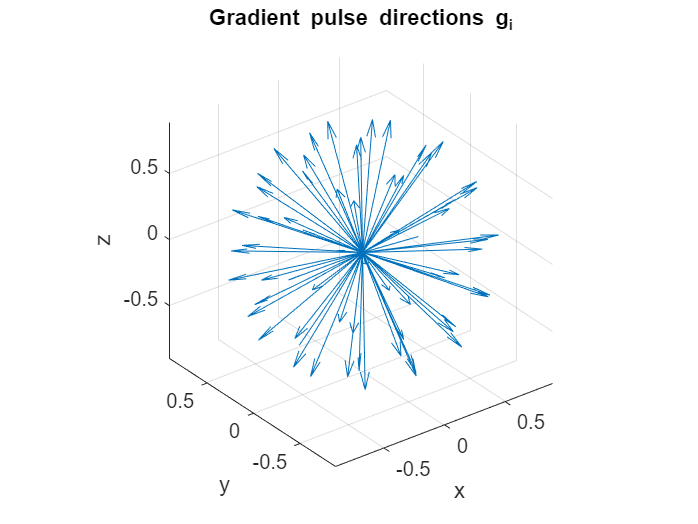

figure
quiver3(0*g(:,1), 0*g(:,1), 0*g(:,1), g(:,1), g(:,2), g(:,3))
axis vis3d
xlabel x, ylabel y, zlabel z
title('Gradient pulse directions g_i')

syms D_xx D_yy D_zz D_xy D_xz D_yz
D = [D_xx D_xy D_xz; D_xy D_yy D_yz; D_xz D_yz D_zz]

$$D = \left(\begin{array}{ccc} D_{\mathrm{xx}} & D_{\mathrm{xy}} & D_{\mathrm{xz}}\\ D_{\mathrm{xy}} & D_{\mathrm{yy}} & D_{\mathrm{yz}}\\ D_{\mathrm{xz}} & D_{\mathrm{yz}} & D_{\mathrm{zz}} \end{array}\right)$$

D_tilde = [D_xx D_yy D_zz D_xy D_xz D_yz]'

$$D\_tilde = \left(\begin{array}{c} \bar{D_{\mathrm{xx}}}\\ \bar{D_{\mathrm{yy}}}\\ \bar{D_{\mathrm{zz}}}\\ \bar{D_{\mathrm{xy}}}\\ \bar{D_{\mathrm{xz}}}\\ \bar{D_{\mathrm{yz}}} \end{array}\right)$$

i = 1:64;
j = 1:115;
k = 1:90;
E = cell(115,90);
B = cell(115,90);
w = cell(115,90);

for j = 1:115
    for k = 1:90
        w{j,k} = squeeze(S(j,k,:)); 
        E{j,k} = ((abs(w{j,k})+w{j,k})./2);
        B{j,k} = ((log(E{j,k}./S0(j,k)))./-b);
       
    end
end

g1 = g(:,1);
g2 = g(:,2);
g3 = g(:,3);
A = [g1.^2 g2.^2 g3.^2 2.*g1.*g2 2.*g1.*g3 2.*g2.*g3]

A =     0.2191    0.0001    0.7808   -0.0108    0.8272   -0.0204
    0.1490    0.0666    0.7845   -0.1992    0.6837   -0.4570
    0.9169    0.0158    0.0673   -0.2404    0.4969   -0.0651
    0.9128    0.0158    0.0714   -0.2402    0.5105   -0.0672
    0.2724    0.0015    0.7260   -0.0408   -0.8895    0.0666
    0.1770    0.0031    0.8200    0.0465   -0.7619   -0.1000
    0.2037    0.7951    0.0012    0.8050   -0.0306   -0.0605
    0.0849    0.9047    0.0104    0.5542   -0.0594   -0.1941
    0.0034    0.6575    0.3391   -0.0944    0.0678   -0.9444
    0.0142    0.6791    0.3066    0.1965   -0.1320   -0.9127


D_tilde = cell(115,90);
D = cell(115,90);
for j = 1:115
    for k = 1:90
        for z = 1:6
       D_tilde{j,k} = A\ B{j,k} ;
       D_tilde{j,k}(isnan(D_tilde{j,k})) = 0;       
       D{j,k} = [D_tilde{j,k}(1) D_tilde{j,k}(4) D_tilde{j,k}(5); D_tilde{j,k}(4) D_tilde{j,k}(2) D_tilde{j,k}(6); D_tilde{j,k}(5) D_tilde{j,k}(6) D_tilde{j,k}(3)] ; 
        end
    end
end

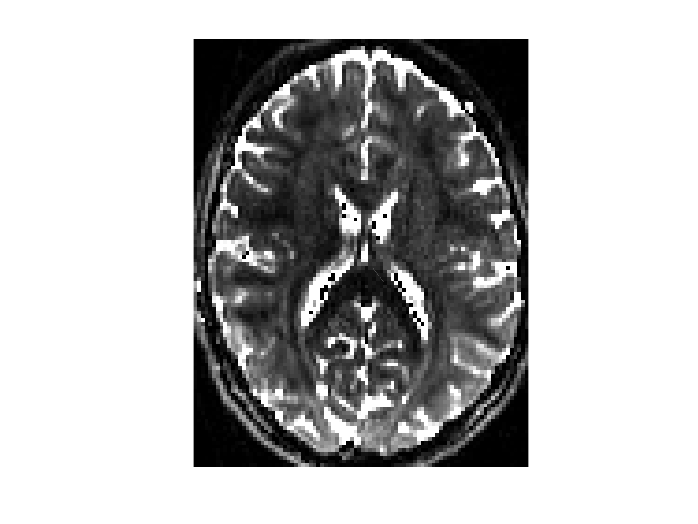

% eigenvalues: lambda1, lambda2, lambda3
d = cell(115,90);
d1 = cell(115,90);
V = cell(115,90);
for j = 1:115
    for k = 1:90
       [V{j,k} d{j,k}] = eig(D{j,k}); 
       d1{j,k} = diag(d{j,k});
    end
end

% Mean Diffusivity = (lambda1 + lambda2 + lambda3)/3
MD = cell(115,90);
for j = 1:115
    for k = 1:90
       MD{j,k} = ((sum(d1{j,k}))/3);
    end
end


for i = 1:64
for j = 1:115
    for k = 1:90
       MDS0(j,k)= MD{j,k}.*S0(j,k) ;
       MDw(j,k) = MD{j,k}.*E{j,k}(i);
       MDt(j,k) = MDS0(j,k) - MDw(j,k);
    end
end
end
figure
imshow(mask, 'initialmagnification', 'fit')
hold on
imshow(real(MDt), 'initialmagnification','fit')
hold off

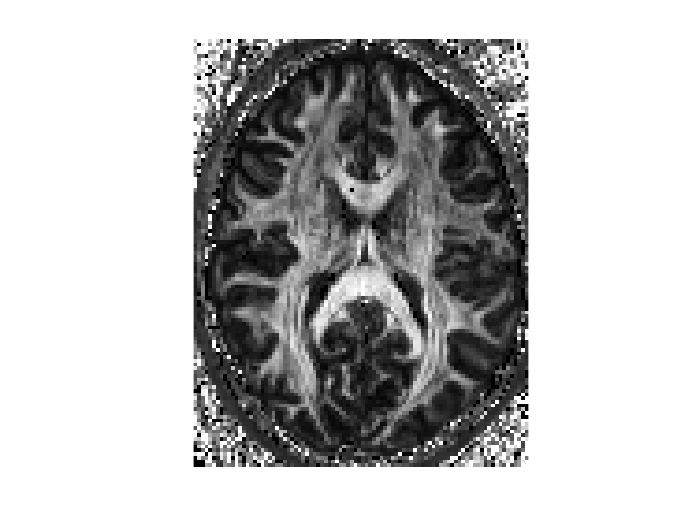

% Fractional Anisotropy 
FA = cell(115,90);
for j = 1:115
    for k = 1:90
       FA{j,k} = sqrt(((d1{j,k}(2)-d1{j,k}(1))^2 + (d1{j,k}(3)-d1{j,k}(2))^2 + (d1{j,k}(3)-d{j,k}(1))^2) ...
       /(2*(d1{j,k}(1)^2 + d1{j,k}(2)^2 + d1{j,k}(3)^2))); 
       FA{j,k}(isnan(FA{j,k})) = 0;
    end
end

FAp = cell2mat(FA);

figure
imshow(mask, 'initialmagnification', 'fit')
hold on
imshow(real(FAp), 'initialmagnification', 'fit')

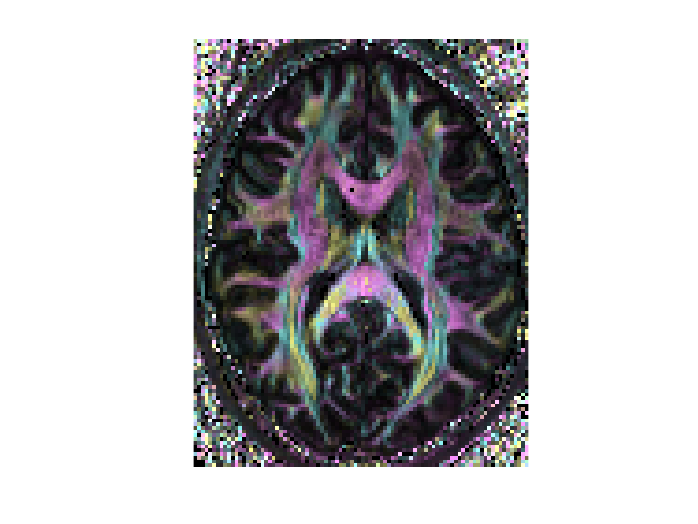

% Principal Diffusion x-axes: red = FA*cos (alpha); y-axes: green = FA*cos(beta); z-axes: blue = FA*cos(gamma)

syms alpha
syms beta
syms gamma

v1 = cell(115,90);
alpha = cell(115,90);
beta = cell(115,90);
gamma = cell(115,90);
PDa = cell(115,90);
PDb = cell(115,90);
PDg = cell(115,90);
Ca = cell(115,90);
Cb = cell(115,90);
Cg = cell(115,90);

for j = 1:115
    for k = 1:90
        v1{j,k} = V{j,k}(:,1);
    end
end
for j = 1:115
    for k = 1:90
        alpha{j,k} = v1{j,k}(1);
        beta{j,k} = v1{j,k}(2);
        gamma{j,k} = v1{j,k}(3);
    end
end
for j = 1:115
    for k = 1:90
        Ca{j,k} = cos(alpha{j,k});
        Cb{j,k} = cos(beta{j,k});
        Cg{j,k} = cos(gamma{j,k});
    end
end

for j = 1:115
    for k = 1:90
        PDa{j,k} = FA{j,k}.*Ca{j,k};
        PDb{j,k} = FA{j,k}.*Cb{j,k};
        PDg{j,k} = FA{j,k}.*Cg{j,k};
    end
end
PDA = cell2mat(PDa);
PDB = cell2mat(PDb);
PDG= cell2mat(PDg);


RGB1 = cat(3,PDA,PDB,PDG);

figure
imshow(mask, 'initialmagnification', 'fit')
hold on
imshow(real(FAp), 'InitialMagnification', 'fit')
hold on
imshow(real(RGB1), 'initialmagnification', 'fit')